cd /home/mic-ciciolla/Documents/università/incompleted/elective/underactuated/hopping-robot-2D/
clear, clc
pause(0.1)
close all
pause(0.1)

# One-Legged Hopping Robot

#### Parameters [m] and [kg]

g=9.81;

M1=1; % Leg mass [kg]
M2=10; % Body mass [kg]

I1=1; % Leg moment of Inertia [kg-m^2]
I2=10; % Body moment of Inertia [kg-m^2]

r1=0.5; % [m]
r2=0.4; % [m]

k0=1; % [m]
KL=10^4; % [Nt/m]

KL2=10^5; % [Nt/m]
BL2=125; % [Nt-s/m]

KG=10^3; % [Nt/m]
BG=75; % [Nt-s/m]

% desired jumping height
H = 0.4;%[m]

#### Initial Conditions

ini_theta1 =0;
ini_theta1_d=0;

ini_theta2 =0;
ini_theta2_d=0;

% ini_w = k0 = 1 ;
ini_w=1;
ini_w_d=0;

% distance [ Leg CoM -- Hip Joint ]
ini_W = ini_w-r1;

## Foot CoM

ini_x0=0;
ini_x0_d=0;

% height
ini_y0 =0.4; % [m]
ini_y0_d=0;

## Leg CoM

ini_x1=ini_x0+r1*cos(pi/2 - ini_theta1);
ini_x1_d=0;

% height
ini_y1=ini_y0+r1*sin(pi/2 - ini_theta1);
ini_y1_d=0;

## Hip Joint location

ini_xH = ini_x1 + ini_W*cos(pi/2 - ini_theta1);
ini_yH = ini_y1 + ini_W*sin(pi/2 - ini_theta1);

## Body Com

ini_x2=ini_xH + r2*cos(pi/2 - ini_theta2);
ini_x2_d=0;

% height
ini_y2=ini_yH + r2*sin(pi/2 - ini_theta2);
ini_y2_d=0;

## Plotting initial setup

foot(1,1) = ini_x0; foot(1,2) = ini_y0;
leg(1,1) = ini_x1; leg(1,2) = ini_y1;
body(1,1) = ini_x2; body(1,2) = ini_y2;
hip(1,1) = ini_xH; hip(1,2) = ini_yH;

% drawRobot(foot,leg,body,hip)

#### Theta1_desired for torque control (equation 1)

theta1_des=0;

**Desired system energy to jump to height H (equation 14) - costant**

desired_energy = M1*g*(H+r1) + M2*g*(H+k0+r2);

**Maximum compression of leg during stance**

deltaw = (M2*g)/KL + sqrt( ((M2^2*g^2)/KL^2) + 2*g*H*(M1+M2)^2/(M2*KL) );

fprintf(2,"\nInitial conditions:\n\nH = %i\nini_y0 = %u\n\nStarting simulink...\n",H,ini_y0)


Initial conditions:

H = 4.000000e-01
ini_y0 = 4.000000e-01

Starting simulink...


**SIMULINK**

simtime = 30; %simulation time
% Execution of the simulation in Simulink
out=sim('simulink/HoppingModel_Last.slx',simtime); 

Found algebraic loop containing: 
HoppingModel_Last/RC LPF height/Add
HoppingModel_Last/RC LPF height/Discrete Derivative/TSamp
HoppingModel_Last/RC LPF height/Discrete Derivative/Diff (algebraic variable)
Found algebraic loop containing: 
HoppingModel_Last/RC LPF vel/Add
HoppingModel_Last/RC LPF vel/Discrete Derivative/TSamp
HoppingModel_Last/RC LPF vel/

% theta2 is the only variable carrying out time values (from 0 to simtime)
t = out.theta2.time;

% creating struct variable state ('name',array)
state = struct('y',[],'x',[],'w',[],'theta1',[],'theta2',[]);
% y0
state.y = out.height;
% x0
state.x = out.horizontal;
% w
state.w = out.lenght;
% theta1
state.theta1 = out.theta1;
% theta2 
state.theta2 = out.theta2.signals.values;

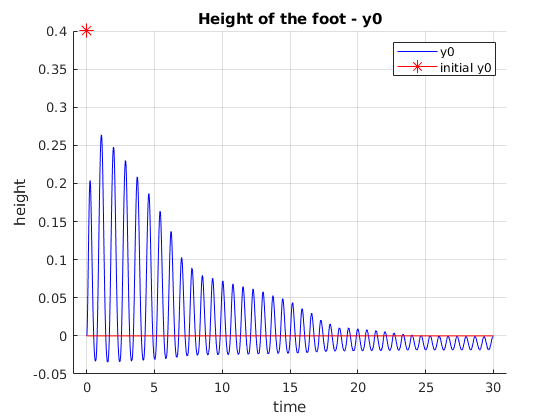

close all
figure()
hold on, grid on
plot(t,state.y,"color",'blue')
title("Height of the foot - y0")
plot(0,ini_y0,"marker","*","MarkerSize",10,"Color","r")
plot(t,zeros(size(t)),"color","r")
xlabel("time")
ylabel("height")
xlim([-1,simtime+1])
legend("y0","initial y0");

cd simulink/
return

## This is an animated plot of the height of the foot

`run this section: CTRL + ENTER`

figure()
grid on, hold on
xlabel("time")
ylabel("height")
plot(0,ini_y0,"marker","*","MarkerSize",10,"Color","r")
% plot(t,zeros(size(t)),"color","red",'LineWidth',0.1)
legend("initial y0");

% line drawing the foot
anfoot = animatedline;
anfoot.Marker = '.';
anfoot.MarkerSize = 0.9;
anfoot.LineStyle = ':';
anfoot.Color = 'k';

% % line drawing the leg
% anleg = animatedline;
% anleg.Marker = '.';
% anleg.MarkerSize = 0.9;
% anleg.LineStyle = ':';
% anleg.Color = 'b';

title("Animation of y0")

xlim([-1,31])
ylim([min(state.y)-0.1, ini_y0+0.1])

% i'm taking one point every 10 to be drawn
for i = 1:10:length(t)
    addpoints(anfoot,t(i),state.y(i))
    drawnow
end


